# SLCO4A - Aula Prática 5

## Sistemas

### Classificação de sistemas

#### SISO - Single-Input Single-Output 

a) A relação que descreve um sistema S é $y\left(t\right)=x\left(t-2\right)$. Compute e plot a resposta do sistema para um sinal de entrada $x\left(t\right)=\textrm{tcos}\left(2\pi \;t\right)$, $0\le t\le 3$.

- 1 unica entrada, unica saida

- atrasa as amostras

- deslocamento temporal de 2 segundos

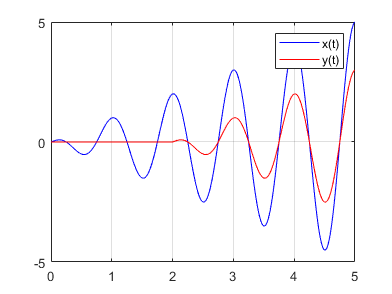

t=0:0.01:3; %3 segundos
%sinal de entrada
x = t.*cos(2*pi*t);
plot(t,x,'b') %deslocamento temporal
hold on
plot(t+2,x,'r')
grid on
legend('x(t)', 'y(t)')
%azul entrada e vermelho saida


%Outra forma de resolver
t=0:0.01:5; %5 segundos
%sinal de entrada
x = t.*cos(2*pi*t);
plot(t,x,'b') %deslocamento temporal

%vetor correspondente ao y
for i = 1:length(t)
    if t(i)<=2
        y(1,i) = 0;
    else 
        y(1,i) = (t(i)-2).*cos(2*pi*(t(i)-2));
    end
end

plot(t, x, 'b', t,y,'r')
legend('x(t)', 'y(t)');
grid on

#### MISO - Multiple-Input Single-Output 

b) Suponha que um sistema MISO S  é descrito pela relação entrada saída $y\left(t\right)=x_1 \left(t\right)+x_2 \left(t\right)x_3 \left(t\right)$. Compute e plot a saída do sistema se os sinais de entrada são dados por $x_1 \left(t\right)=u\left(t\right)-u\left(t-3\right)$, $x_2 \left(t\right)=t\;\sin \left(t\right)$ e $x_3 \left(t\right)=t\;\cos \left(t\right)$, $0\le t\le 4$.

multplicas entradas e uma saida

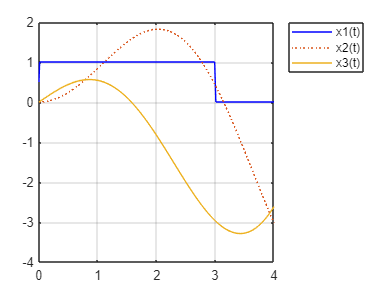

figure
t=0:0.01:4;
x1 = heaviside(t)-heaviside(t-3);
x2 = t.*sin(t);
x3 = t.*cos(t);
plot(t,x1,'b', t, x2, ':', t, x3, '-') 
legend('x1(t)', 'x2(t)', 'x3(t)', 'Location','bestoutside');
grid on

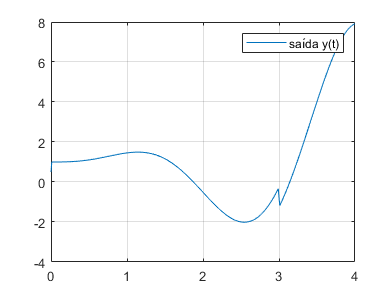


y = x1+ x2.*x3;
plot(t,y)
grid on
legend('saída y(t)')

#### SIMO - Single-Input Multiple-Output 

c) Suponha que um sistema SIMO S  é descrito pelas relações  $y_1 \left(t\right)=x_1^2 \left(t\right)$e $y_2 \left(t\right)=1-3x_1 \left(t\right)$. Compute e plot a saída do sistema se o sinal de entrada é dado por $x_1 \left(t\right)=t\;\cos \left(t\right)$, $0\le t\le 4$.

 uma entrada e multiplas saidas

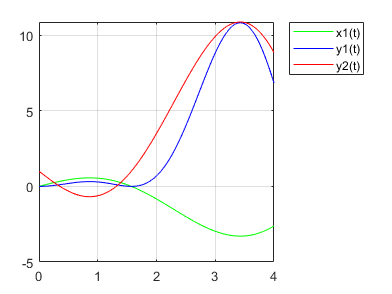

t=0:0.01:4;
x1=t.*cos(t);
y1=x1.^2; %saida
y2=1-3.*x1;
plot(t,x1,'g',t,y1, 'b', t,y2,'r')
legend('x1(t)', 'y1(t)', 'y2(t)', 'Location','bestoutside');
grid on

#### MIMO - Multiple-Input Multiple-Output 

d) Suponha que um sistema MIMO S  é descrito pelas relações de entrada saída $y_1 \left(t\right)=x_1 \left(t\right)+x_2 \left(t\right)$ e $y_2 \left(t\right)=x_1 \left(t\right)-x_2 \left(t\right)$. Compute e plot a saída do sistema se os sinais de entrada são dados por $x_1 \left(t\right)=u\left(t\right)$, $x_2 \left(t\right)=0\ldotp 5u\left(t-1\right)$, $0\le t\le 4$.

multiplas entradas e multiplas saidas

t=0:0.01:4;
x1 = heaviside(t);
x2 = 0.5*heaviside(t-1); %degrau deslocado ponderado
y1 = x1+x2

y1 =     0.5000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


y2= x1 - x2

y2 =     0.5000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


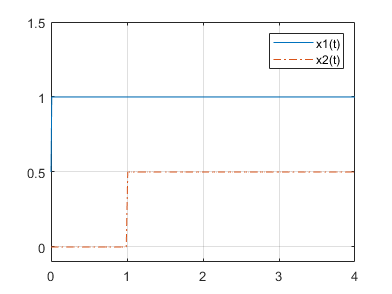

plot(t,x1,t,x2,'-.')
grid on
ylim([-0.1 1.5])
legend('x1(t)', 'x2(t)');

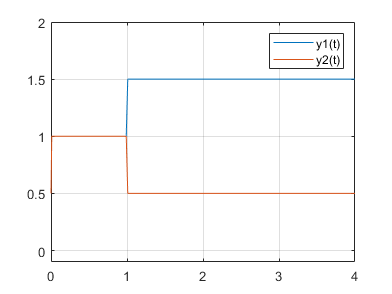


plot(t,y1,t,y2)
legend('y1(t)', 'y2(t)');
grid on
ylim([-0.1 2])

### Propriedades de sistemas

#### Causal e não causal

e) Suponha que o sistema S1 é descrito pela relação de entrada saída $y_1 \left(t\right)=x\left(t+1\right)$enquanto que do sistema S2 é dada por $y_2 \left(t\right)=x\left(t-1\right)$. Considerando que o sinal de entrada é $x\left(t\right)=u\left(t\right)-u\left(t-1\right)$, $-3\le t\le 3$. Determine se os dois sistemas são causais.

t = -1:0.01:3

t =    -1.0000   -0.9900   -0.9800   -0.9700   -0.9600   -0.9500   -0.9400   -0.9300   -0.9200   -0.9100   -0.9000   -0.8900   -0.8800   -0.8700   -0.8600   -0.8500   -0.8400   -0.8300   -0.8200   -0.8100   -0.8000   -0.7900   -0.7800   -0.7700   -0.7600   -0.7500   -0.7400   -0.7300   -0.7200   -0.7100   -0.7000   -0.6900   -0.6800   -0.6700   -0.6600   -0.6500   -0.6400   -0.6300   -0.6200   -0.6100   -0.6000   -0.5900   -0.5800   -0.5700   -0.5600   -0.5500   -0.5400   -0.5300   -0.5200   -0.5100


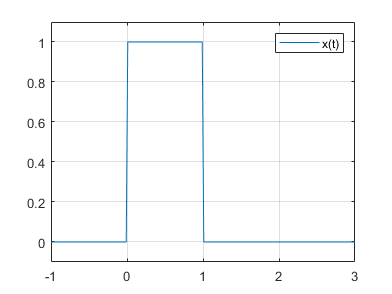

%entrada
x=heaviside(t)-heaviside(t-1);
figure
plot(t,x)
grid on
ylim([-0.1 1.1])
legend('x(t)')

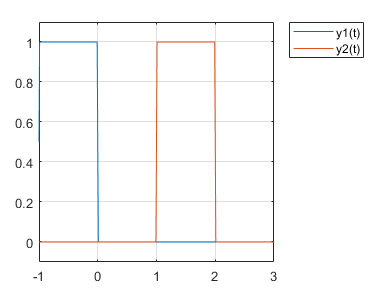


%saida
y1=heaviside(t+1)-heaviside((t+1)-1);
y2=heaviside(t-1)-heaviside((t-1)-1);
plot(t,y1, t, y2)
grid on
ylim([-0.1 1.1])
legend('y1(t)', 'y2(t)', 'Location', 'bestoutside' )


%sistema   2 é causal pq o sinal de entrada ele veio no instante depois (veio por causa do sinal de entrada -justifica pelo passado) 
% o azul nao é causal pq ele nao se justifica. ele ocorreu no futuro, nao
% temos predição do sinal de entrada do futuro. por isso nao é causal.
%sistema 2 causal e sistema 1 nao


#### Estático (sem memória) e dinâmico (com memória)

f) Usando o sinal de entrada $x\left(t\right)=u\left(t\right)-u\left(t-1\right)$, $-3\le t\le 3$, determine se os sistemas descritos pelas relações de entrada saída $y_1 \left(t\right)=3x\left(t\right)$e $y_2 \left(t\right)=x\left(t\right)+x\left(t-1\right)$ são estático ou dinâmico.

t = -1:0.01:3

t =    -1.0000   -0.9900   -0.9800   -0.9700   -0.9600   -0.9500   -0.9400   -0.9300   -0.9200   -0.9100   -0.9000   -0.8900   -0.8800   -0.8700   -0.8600   -0.8500   -0.8400   -0.8300   -0.8200   -0.8100   -0.8000   -0.7900   -0.7800   -0.7700   -0.7600   -0.7500   -0.7400   -0.7300   -0.7200   -0.7100   -0.7000   -0.6900   -0.6800   -0.6700   -0.6600   -0.6500   -0.6400   -0.6300   -0.6200   -0.6100   -0.6000   -0.5900   -0.5800   -0.5700   -0.5600   -0.5500   -0.5400   -0.5300   -0.5200   -0.5100


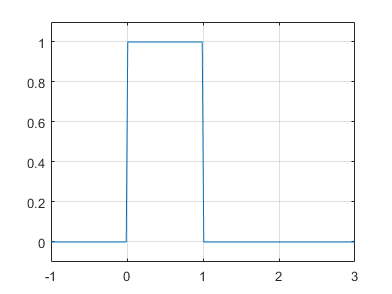

%entrada
x=heaviside(t)-heaviside(t-1);
figure
plot(t,x)
grid on
ylim([-0.1 1.1])

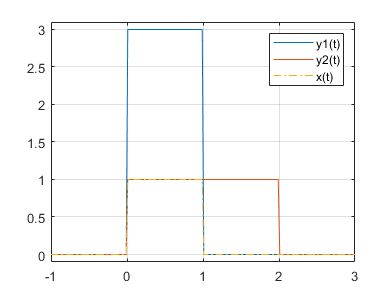



y1 = 3.*x;
%[u(t) - u(t-1)] + [u(t-1)-u(t-2)] 
%y2 = entrada atual x(t) + entrada deslocada x(t-1)
%y2 = u(t) - u(t-2)
y2 = heaviside(t)-heaviside(t-2);
figure
plot(t,y1,t,y2,t,x,'-.')
grid on
legend('y1(t)', 'y2(t)', 'x(t)')
ylim([-0.1 3.1])


%y1 só depende da amostra atual, n precisa armazenar valor para fazer uma
%operação: sistema estatico, sem memoria
%sistema dinamico q depende de uma memoria/ amostras passadas -  y2  
% ele pega as amostras do intervalo de tempo da entrada y1

#### Linear e não linear


$$S\left\lbrace a_1 {\;x}_1 \left(t\right)+a_2 {\;x}_2 \left(t\right)\right\rbrace =a_1 S\left\lbrace x_1 \left(t\right)\right\rbrace \;+a_{2\;} S\left\lbrace x_2 \left(t\right)\right\rbrace$$


A resposta de um sistema linear para uma entrada que é a combinação linear de dois sinais corresponde a uma combinação linear das respostas do sistema para cada uma destes sinais de entrada. (Princípio da superposição = aditividade + homogenidade).

g) Dado $x_1 \left(t\right)=u\left(t\right)-u\left(t-1\right)$ e $x_2 \left(t\right)=u\left(t\right)-u\left(t-2\right)$ sejam considerados sinais de netrada para os sistemas descritos pelas seguintes relações $y\left(t\right)=2x\left(t\right)$ e $z\left(t\right)=x^2 \left(t\right)$, $-3\le t\le 3$. Determine se a propriedade de linearidade é válida para estes dois sistemas.

Solução: adotando os escalares $a_1 =2$ e $a_2 =3$

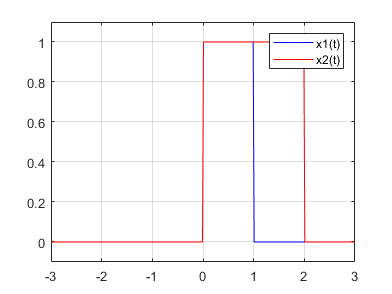

t=-3:0.01:3;
x1=heaviside(t)-heaviside(t-1);
x2=heaviside(t)-heaviside(t-2);
plot(t,x1,'b',t,x2,'r')
grid on
ylim([-0.1 1.1])
legend('x1(t)', 'x2(t)')

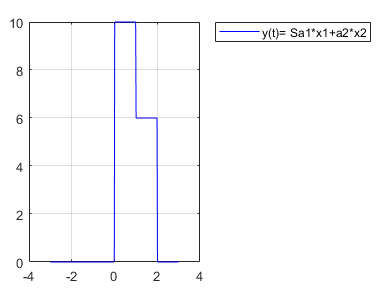


%Sistema 1 y(t) = 2*x(t)
a1=2; %ganho'
a2=3; %ganho''
%combinacao linear das entradas
%x(t)=a1*x1+a2*x2 => y(t) = S{a1*x1+a2*x2}
s=a1*x1+a2*x2;
ys=2*s;
plot(t,ys,'b')
grid on
legend('y(t)= S{a1*x1+a2*x2}', 'Location', 'bestoutside')

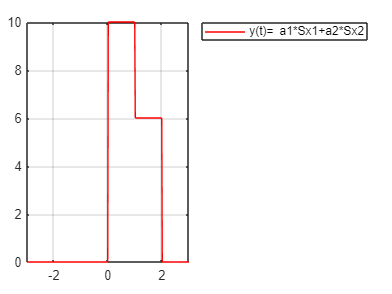


y1=2*x1;
y2=2*x2;
ys2=a1*y1+a2*y2;
plot(t,ys2, 'r')
grid on
legend('y(t)= a1*S{x1}+a2*S{x2}', 'Location', 'bestoutside')

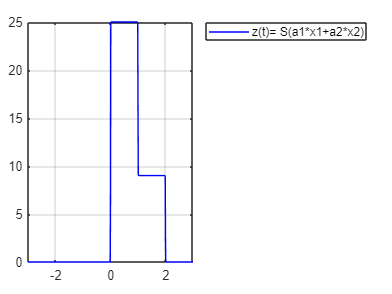


%Sistema 2 => y(t) = x(t)^2
%s=a1*x1+a2*x2;
z=s.^2;
plot(t,z,'b')
grid on
legend('z(t)= S(a1*x1+a2*x2)', 'Location', 'bestoutside')

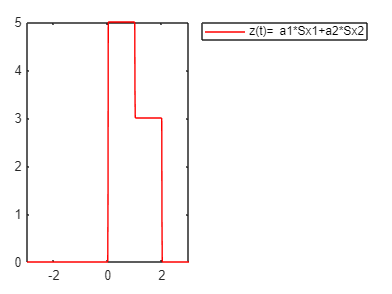

%amplitude 25, depois 9... no intervalo de 1s

z1=x1.^2;
z2=x2.^2;
zs2=a1*z1+a2*z2;
plot(t,zs2,'r')
legend('z(t)= a1*S{x1}+a2*S{x2}', 'Location', 'bestoutside')

%combinacao das saidas do sistema
%nao é um sistema linear. 



#### Invariante no tempo e variante no tempo

Se $y\left(t\right)$é a resposta de um sistema invariante no tempo para uma entrada $x\left(t\right)$, então a resposta do sistema para um sinal de entrada $x\left(t-t_0 \right)$é $y\left(t-t_0 \right)$.


$$y\left(t-t_0 \right)=S\left\lbrace x\left(t-t_0 \right)\right\rbrace$$


h) Suponha que a resposta de um sistema S para um sinal de entrada $x\left(t\right)$é $y\left(t\right)={t\;e}^{-t} x\left(t\right)$. Determine se este sistema é invariante no tempo para uma entrada $x\left(t\right)=u\left(t\right)-u\left(t-5\right)$, $-3\le t\le 10$.

        1. Avaliar $y\left(t\right)=S\left\lbrace x\left(t\right)\right\rbrace$

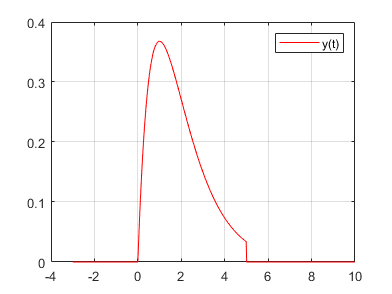

t=-3:0.01:10;
x=heaviside(t)-heaviside(t-5); %entrada deslocada em 3 s
y=t.*exp(-t).*x; %saida
figure
plot(t,y, 'r') %resp
grid on
legend('y(t)')

        2. Obter $y\left(t-t_0 \right)$, $t_0 =3$

%avaliacao do deslocamento temporal apenas da saida
figure
plot(t+3,y)
grid on
hold on


        3. Obter $S\left\lbrace x\left(t-t_0 \right)\right\rbrace$, $t_0 =3$ e comparar com o passo 2.

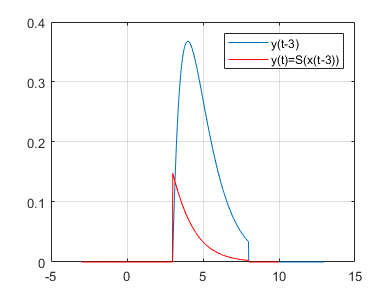

%invariante no tempo
t=-3:0.01:10;
x=heaviside(t-3)-heaviside(t-3-5); %entrada
y=t.*exp(-t).*x; %saida
plot(t,y,'r')
grid on
legend('y(t-3)','y(t)=S(x(t-3))')


%invariante no tempo - resposta igual 
%variante - resposta diferente como esse exercicio

#### Estável e instável

BIBO - *Bounded-Input Bounded Output*

Para um pequeno sinal aplicado na entrada a resposta do sistema também é pequena e não diverge. Ou seja, se um dado número positivo existe $M<\infty$, tal que $\left|x\left(t\right)\right|\le M$. O sistema é estável se $\forall t\in \Re$ um número positivo $N<\infty$, tal que $\left|y\left(t\right)\right|\le N$.

i) Suponha que um sinal de entrada $x\left(t\right)=\cos \left(2\pi \;t\right)$é aplicado a dois sistemas descritos pela relação de entrada saída $y_1 \left(t\right)=x^2 \left(t\right)$e $y_2 \left(t\right)=t\;x\left(t\right)$, $0\le t\le 10$. . Determine se estes sistemas são estáveis.

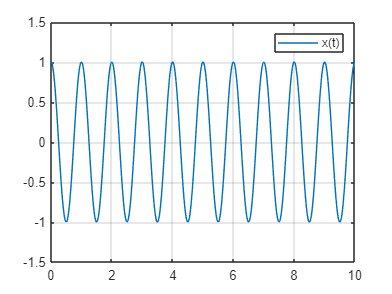

%ao palicar uma entrada limitada, ve se a saida é limitada
t = 0:0.01:10;
x = cos(2*pi*t);
figure
plot(t,x)
grid on
ylim([-1.5 1.5])
legend('x(t)')


%sistema 1 estavel
y1=x.^2

y1 =     1.0000    0.9961    0.9843    0.9649    0.9382    0.9045    0.8645    0.8187    0.7679    0.7129    0.6545    0.5937    0.5314    0.4686    0.4063    0.3455    0.2871    0.2321    0.1813    0.1355    0.0955    0.0618    0.0351    0.0157    0.0039    0.0000    0.0039    0.0157    0.0351    0.0618    0.0955    0.1355    0.1813    0.2321    0.2871    0.3455    0.4063    0.4686    0.5314    0.5937    0.6545    0.7129    0.7679    0.8187    0.8645    0.9045    0.9382    0.9649    0.9843    0.9961


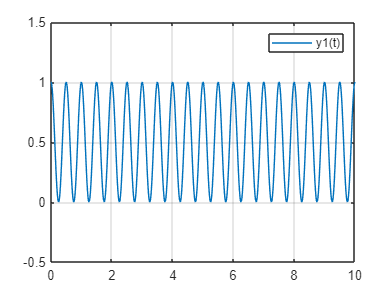

plot(t,y1)
grid on
ylim([-0.5 1.5])
legend('y1(t)')


%sistema 2 instavel
y2 = t.*x

y2 =          0    0.0100    0.0198    0.0295    0.0387    0.0476    0.0558    0.0633    0.0701    0.0760    0.0809    0.0848    0.0875    0.0890    0.0892    0.0882    0.0857    0.0819    0.0766    0.0699    0.0618    0.0522    0.0412    0.0288    0.0151    0.0000   -0.0163   -0.0338   -0.0525   -0.0721   -0.0927   -0.1141   -0.1362   -0.1590   -0.1822   -0.2057   -0.2295   -0.2533   -0.2770   -0.3005   -0.3236   -0.3462   -0.3680   -0.3891   -0.4091   -0.4280   -0.4455   -0.4617   -0.4762   -0.4890


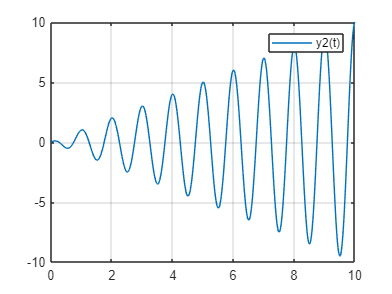

plot(t,y2)
grid on
legend('y2(t)')

#### Invertível e não invertível

Um sistema é invertível se um sinal de entrada $x\left(t\right)$que é aplicado ao sistema pode ser derivado a partir da resposta do sistema $y\left(t\right)$. Ou seja, um sistema é invertível se a relação entrada saída $y\left(t\right)=S\left\lbrace x\left(t\right)\right\rbrace$é uma para uma, isto é, diferentes valores de entrada correspondem a distintos valores de saída.

j) Determine se os sistemas S1 e S2 descritos pelas relações de entrada saída $y_1 \left(t\right)=3x\left(t\right)$e $y_1 \left(t\right)=x^2 \left(t\right)$, respectivamente, são invertíveis. Considere $x\left(t\right)=2\;t$, $-2\le t\le 2\ldotp$

t = -2:2;
x=2*t

x =     -4    -2     0     2     4


y1=3*x

y1 =    -12    -6     0     6    12


y2=x.^2

y2 =     16     4     0     4    16


- Sistema inverso

            
$$z\left(t\right)=S^{-1} \left\lbrace y\left(t\right)\right\rbrace$$


z1= 1/3*y1 %sistema 1 invertivel , sinal de saida obtenho da entrada

z1 =     -4    -2     0     2     4


z2 = sqrt(y2) %n obtem os sinais de entrada original - nao invertivel

z2 =      4     2     0     2     4
